clc
clear
close all
N = 3;
l = 0.5;
c = 1496;
%c = 343;
%freqs = [250 1000 4000 12e3];
freqs = linspace(0e3, 24e3, 241);
%freqs = [1000];
thetas = linspace(0,2*pi,360);
CO = zeros(length(freqs),length(thetas));
logCO = zeros(length(freqs),length(thetas));
artiDelays = flip((0:N-1))*l*cosd(-90)/c

artiDelays =      0     0     0


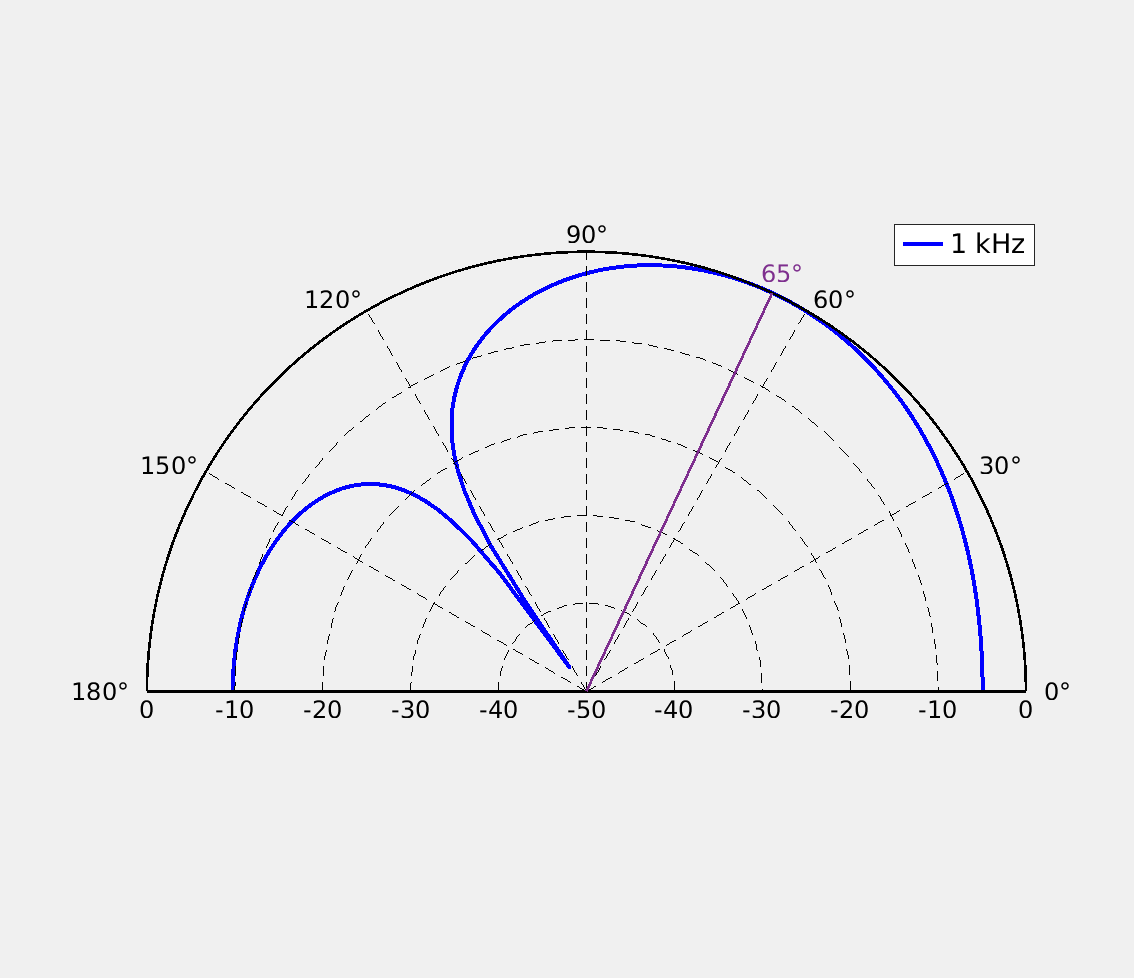


for b=1:length(freqs)
    for q=1:length(thetas)
        realSum = 0;
        imagSum = 0;
        for n=0:N-1
            position = n*l;
            %delay = position*sin(thetas(q))/c;
            theta_s = 65;
            delay = (position*(cos(thetas(q))+sind(theta_s-90)))/c;
            %delay = delay + artiDelays(n+1);
    
            realSum = realSum+cos(2*pi*freqs(b)*delay);
            imagSum = imagSum+sin(2*pi*freqs(b)*delay);

            %realSum = realSum+cos(2*pi*freqs(b)*(delay + artiDelays(n+1)));
            %imagSum = imagSum+sin(2*pi*freqs(b)*(delay + artiDelays(n+1)));
        end
         CO(b,q) = sqrt(realSum*realSum+imagSum*imagSum)/N;
         logCO(b,q) = 20*log10(CO(b,q));
    end
end

% figure()
% logCO(logCO<-62) = -62; %*180/pi+90
% polarpattern(thetas*180/pi,logCO', 'AngleResolution', 45, ...
%     'TitleTop', 'Directivity Pattern ULA', 'TitleBottom', ...
%     'M = 3, c = 343 m/s, δ = 10 cm', 'LineWidth', 3, 'MagnitudeLim', ...
%     [-80 0], 'ColorOrderIndex', 2)%, 'ColorOrder', [0 0 0])
% hold on
% legends = strcat(num2str(freqs(:)), ' Hz')
% legend(legends, 'FontSize', 18, 'Location', 'best')
% hold off

figure(1)
set(gcf,'Visible','on', 'Units', 'centimeters',...
          'OuterPosition', [0 0 30 20])
circPlot(freqs(11), thetas, logCO(11,:), theta_s)
%circPlot(freqs(1), thetas, logCO(1,:), theta_s)
%exportgraphics(gcf,'DAS1kHz.pdf')

figure(2)
set(gcf,'Visible','on', 'Units', 'centimeters',...
          'OuterPosition', [0 0 30 31])

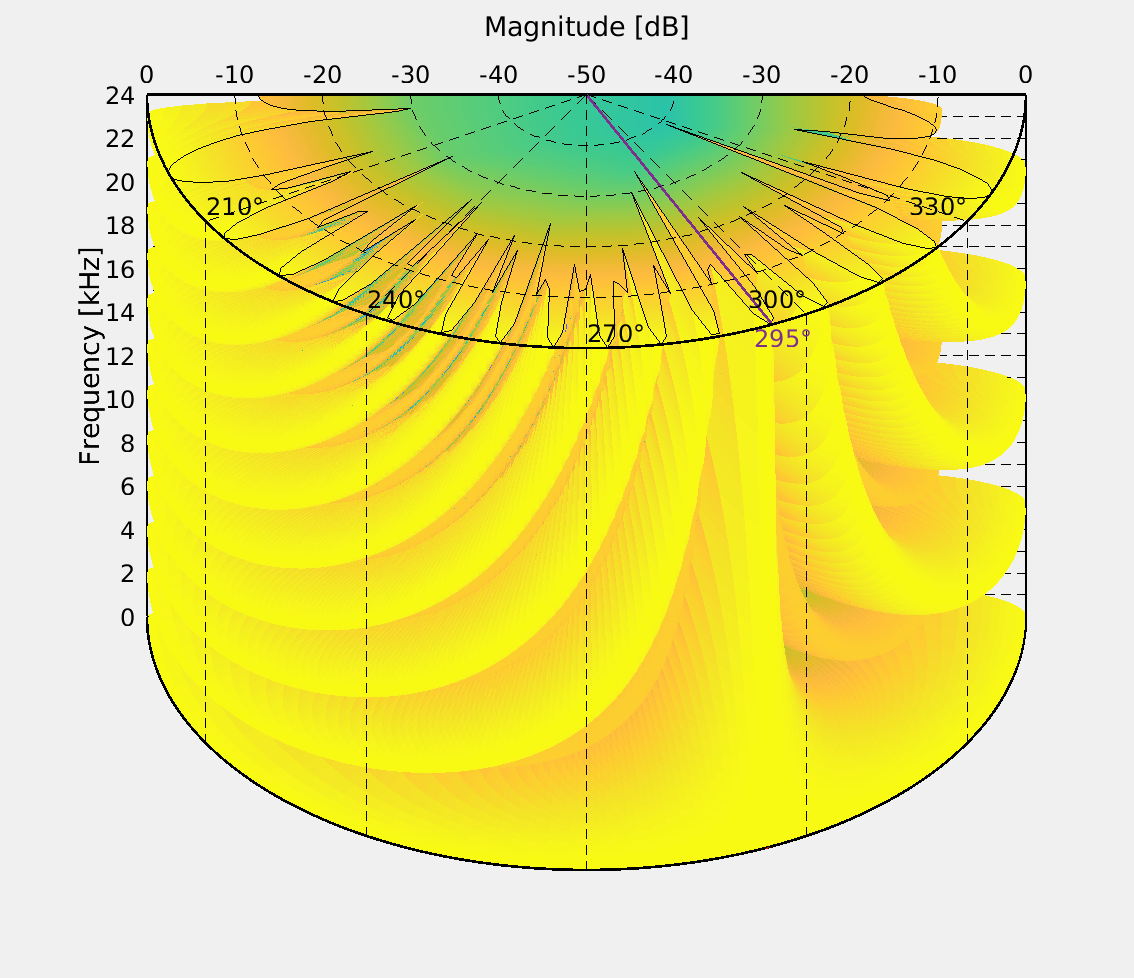

cylindricalPlot(freqs, thetas, logCO, theta_s)

%exportgraphics(gcf,'DAS3D.pdf')

## Fancy DAS

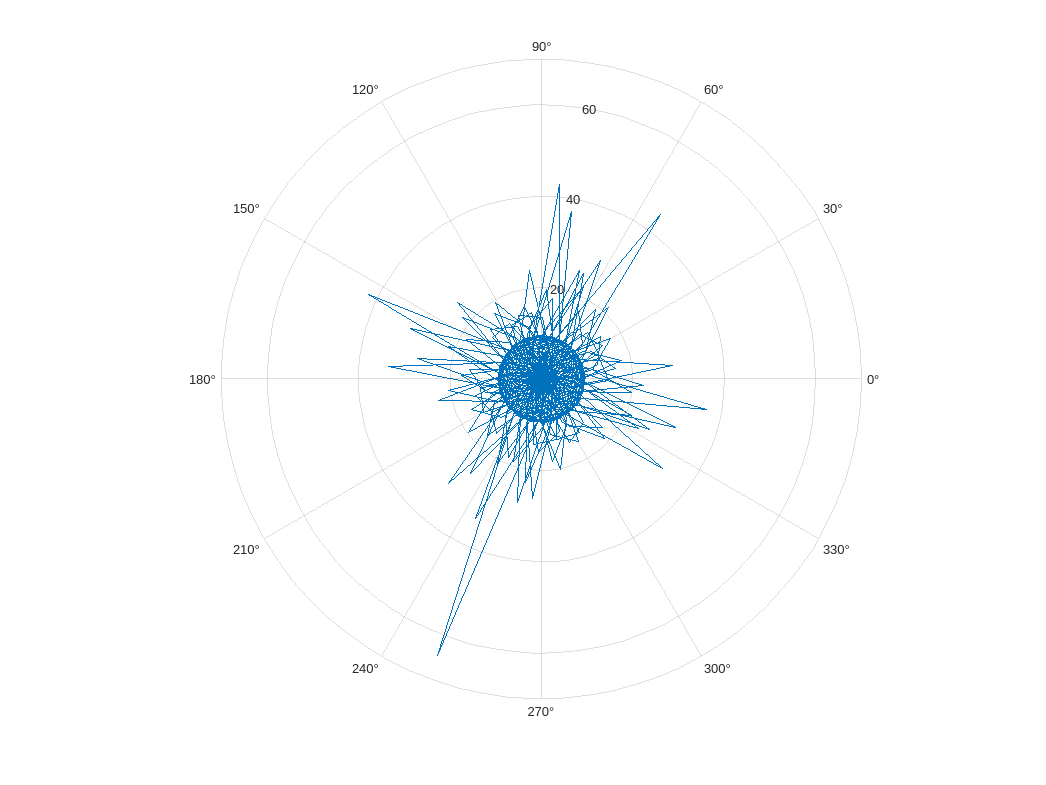

clc
close all 
clear

l = 0.2;
M = 3;
f = 10e3;
c = 343;
delta = (0:M-1)*l;
thetas = linspace(0,2*pi,1000)';
omega = 2*pi*f;
output = zeros(length(thetas),M);
CO = zeros(length(thetas),1); 
for q=1:length(thetas)
    output(q,:) = exp(-1i*omega*thetas(q).*delta/c);
    CO(q) = 20*log10(sum(output(q,:)));
end
polarplot(thetas*180/pi,CO)

## DMA

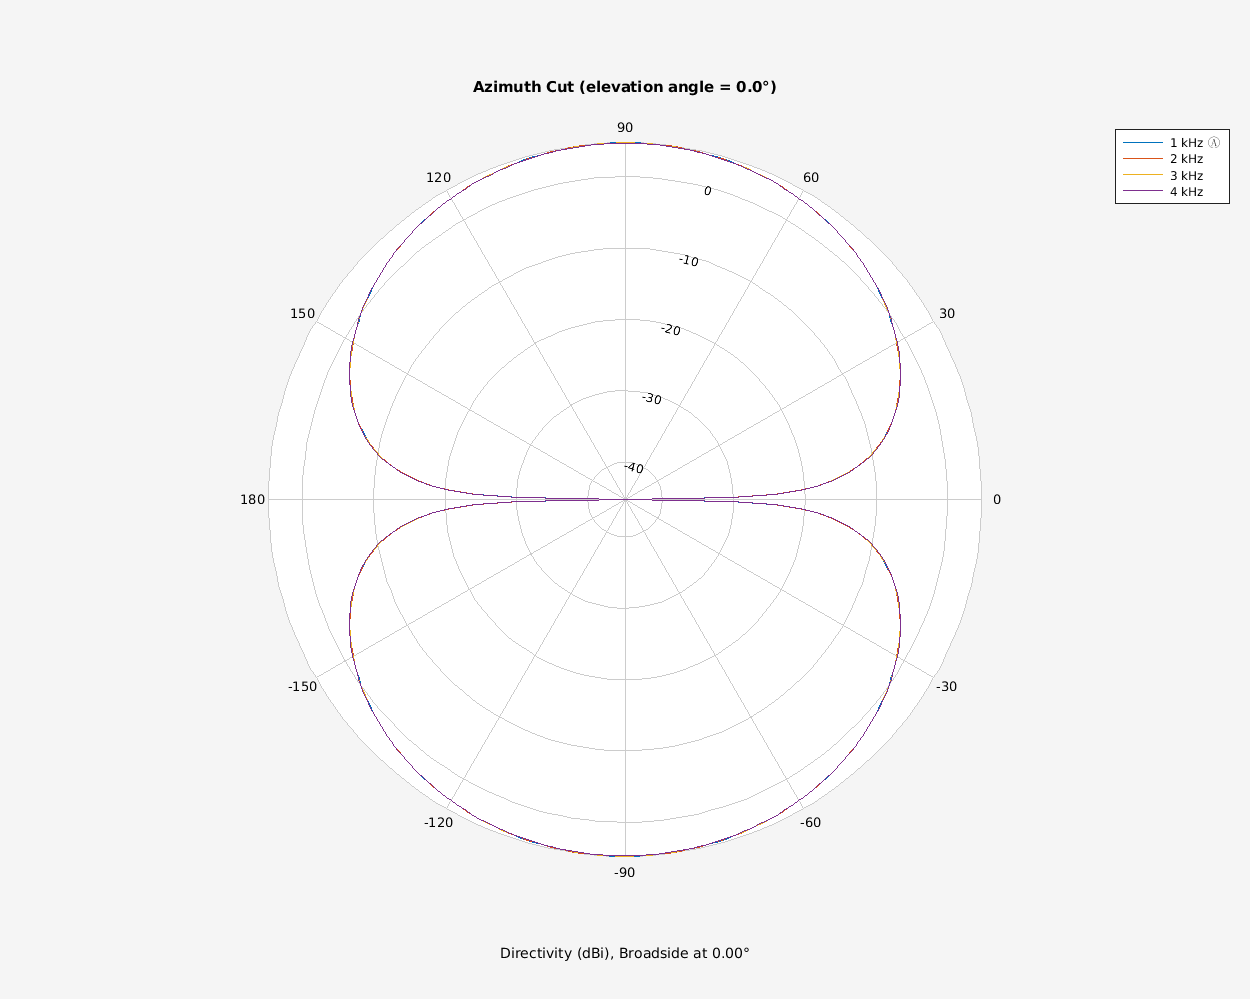

close all
clc 
clear

c = 343;
f = (1:4)*1e3;
fmax = f(end);
lambda = c/fmax;
N = 2;
dd = lambda/10;

micarrayd = phased.ULA(N,dd);

ang_d = 90;  % endfire
ang_n = 0;   % broadside
dd_f = dd./(c./f);
w = complex(zeros(N,numel(f)));
for m = 1:numel(f)
    w(:,m) = diffbfweights(N,dd_f(m),ang_n,'ArrayGeometry','ULA');
end

clf;
pattern(micarrayd,f,-180:180,0,'PropagationSpeed',c,'Weights',w);